clc
clear
clf

%% Model Parameters
m_r = 0.082;
m_w = 0.002;
l_r = 0.35;
m_p = 0.084;
COMp = (m_r*(l_r/2)+ m_w*l_r)/(m_r + m_w);
l= COMp;
I1 = (1/3)*m_p*l^2 ;  % I med l

%% Constants
M = 0.5;
m_p = 0.084;
b_c = 5;
b_p = 0.0012;
g = 9.82;
l = 0.1792;
l= 0.35;            %??? WHY THIS ???
I = (1/3)*m_p*(0.35^2);  % I med 2l

% State space model
A = [0 1 0 0; 0 -b_c/(M+(m_p*I)/(m_p*l^2+I)) (m_p^2*l^2*g)/(M*(m_p*l^2+I)+m_p*I) (m_p*l*b_p)/(M*(m_p*l^2+I)+m_p*I); 0 0 0 1; 0 -(m_p*l*b_c)/(I*(M+m_p)+M*m_p*l^2) (m_p*g*l*(M+m_p))/(I*(M+m_p)+M*m_p*l^2) -(b_p*(M+m_p))/(I*(M+m_p)+M*m_p*l^2)]

A =          0    1.0000         0         0
         0   -9.5969    1.1874    0.0049
         0         0         0    1.0000
         0  -20.5648   23.5874   -0.0980


B = [0; 1/(M+(m_p*I)/(m_p*l^2+I)); 0; (m_p*l)/(I*(M+m_p)+M*m_p*l^2)]

B =          0
    1.9194
         0
    4.1130


C = [1 0 0 0; 0 0 1 0]

C =      1     0     0     0
     0     0     1     0


D = [0; 0];

% Converting state space to transfer functions
rank = rank(ctrb(A,B));
s = tf('s');
sys = ss(A,B,C,D);
tfCart = minreal(tf(sys(1)))

tfCart =
 
      1.919 s^2 + 0.2085 s - 40.39
  -------------------------------------
  s^4 + 9.695 s^3 - 22.55 s^2 - 201.9 s
 
Continuous-time transfer function.



tfPendulum = minreal(tf(sys(2)))

tfPendulum =
 
         4.113 s - 7.346e-15
  ---------------------------------
  s^3 + 9.695 s^2 - 22.55 s - 201.9
 
Continuous-time transfer function.



% Controller Variables
%Pendlum
%Kp = 0.52;
%Ti = 1;
%Td = 20;
%N = 10;
Kp = 366.069991564719;
Ti = 3701.82722683723;
Td = 8.8851655469107;
N = 1126.11038715991;
%Cart
Kpc = -843.8063316859;
Tic = -200.862441767316;
Tdc = 59.7349659468271;
Nc = 8.95379916090364;
%Kpc = 100;
%Tic = 50;
%Tdc = 20;
%Nc = 10;


% PID Controller Cart
%K = Kp*(1 + 1/(Ti*s) + (Td*s)/(1+s*Td/N));
KpidC = 1 + 1/(Tic*s) + (Tdc*s)/(1+s*Tdc/Nc);

% PID Controller Pendulum
%KpidP = 1 + ((s-z1)*(s-z2)*(s-z3))/(Ti*s) + (Td*s)/(1+s*Td/N);
KpidP = 1 + 1/(Ti*s) + (Td*s)/(1+s*Td/N);
% The two transferfunctions multiplied
G = tfCart * tfPendulum

G =
 
               7.894 s^3 + 0.8575 s^2 - 166.1 s + 2.967e-13
  -----------------------------------------------------------------------
  s^7 + 19.39 s^6 + 48.9 s^5 - 841 s^4 - 3407 s^3 + 9106 s^2 + 4.078e04 s
 
Continuous-time transfer function.




% Pole zero maps of the different transfer functions
[p,z] = pzmap(tfPendulum)

p =    -9.9145
    4.6243
   -4.4048


z = 1.7860e-15

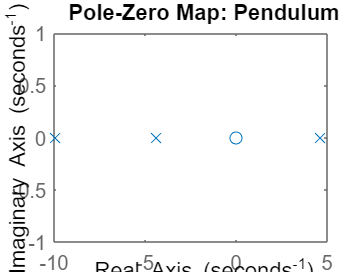

pzplot(tfPendulum)
title('Pole-Zero Map: Pendulum')

[p,z] = pzmap(tfCart)

p =          0
   -9.9145
    4.6243
   -4.4048


z =    -4.6419
    4.5333


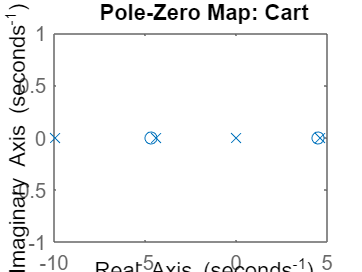

pzplot(tfCart)
title('Pole-Zero Map: Cart')

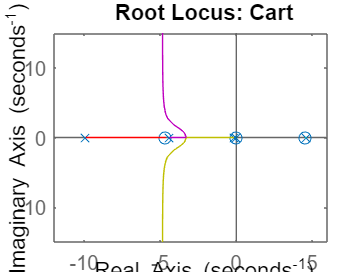

%[p,z] = pzmap(G)
%pzplot(G)
%title('Pole-Zero Map: Cart*Pendulum')

% Root locus plots of the transferfunctions
%zc = [-2 -1];
%pc = 0;
%kc = 1;
%Cc = zpk(zc,pc,kc)
%rlocus(Cc*tfCart)
rlocus(KpidC * tfCart)
title('Root Locus: Cart')

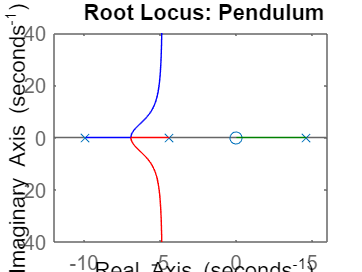

%rlocus(KpidP*tfPendulum)
rlocus(tfPendulum)
%rlocus(-tfPendulum*1/(s-1))
%z = [-3 -2 -1];
%p = 0;
%k = 1;
%Cp = zpk(z,p,k)
%rlocus(Cp*tfPendulum)
title('Root Locus: Pendulum')


%rlocus(Kpid * G)
%title('Root Locus: Cart*Pendulum')

% Random Shit for tests
%zero((Kpid*G)/(1+Kpid*G))
%L = G*Kpid
%Lz = c2d(L, 1/5, 'tustin')
%rlocus(Kpid1*tfPendulum)
%bode(G)

% Step response for the system
K = Kp * KpidP;
G1 = (K * tfPendulum) / (1 + K * tfPendulum)

G1 =
 
                                                                                                                       
       1.836e15 s^8 + 2.507e17 s^7 + 2.243e18 s^6 - 5.368e18 s^5 - 4.762e19 s^4 - 5.284e18 s^3 - 1.427e15 s^2 + 2.549 s
                                                                                                                       
  ---------------------------------------------------------------------------------------------------------------------------
                                                                                                                             
  1.082e09 s^10 + 2.952e11 s^9 + 1.859e15 s^8 + 2.51e17 s^7 + 2.243e18 s^6 - 5.383e18 s^5 - 4.768e19 s^4 - 5.115e18 s^3      
                                                                                                                             
                                                                                                     + 7.073e17 s^2 + 2.549 s
   

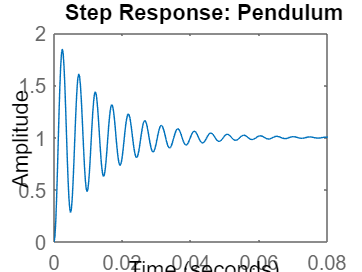

step(G1)
%step(tfPendulum)
title('Step Response: Pendulum')

K2 = Kpc * KpidC;
G2 = (K2 * tfCart) / (1 + K2 * tfCart)

G2 =
 
                                                                                                                             
  -2.321e12 s^10 - 2.313e13 s^9 + 9.497e13 s^8 + 9.64e14 s^7 - 8.941e14 s^6 - 1.003e16 s^5 - 1.624e15 s^4 - 2.077e13 s^3     
                                                                                                                             
                                                                                                               + 1.108e11 s^2
                                                                                                                             
  ---------------------------------------------------------------------------------------------------------------------------
                                                                                                                             
  1.44e08 s^12 + 2.835e09 s^11 - 2.313e12 s^10 - 2.325e13 s^9 + 9.444e13 s^8 + 9.652e14 s^7 - 8.878e14 s^6 - 1.

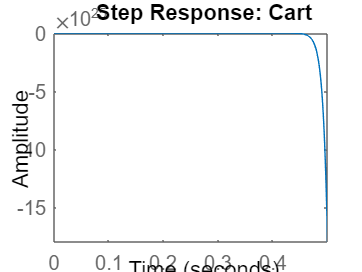

%step(tfCart)
step(G2)
title('Step Response: Cart')

Cascade control:

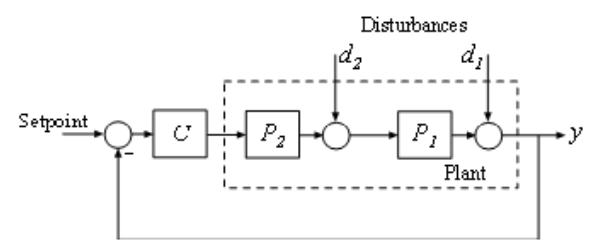

C = pidstd(Kp,Ti,Td,N);
C = pidtune(G,C,0.2);

C

C =
 
             1      1              s      
  Kp * (1 + ---- * --- + Td * ------------)
             Ti     s          (Td/N)*s+1 

  with Kp = -6.46, Ti = 857, Td = 190, N = 4.35e+03
 
Continuous-time PIDF controller in standard form




% First parameter is P2.
C2 = pidtune(tfCart,pidstd(Kp,Ti,Td,N),2);
C2

C2 =
 
             1      1              s      
  Kp * (1 + ---- * --- + Td * ------------)
             Ti     s          (Td/N)*s+1 

  with Kp = -0.269, Ti = 85.7, Td = 19, N = 4.35e+03
 
Continuous-time PIDF controller in standard form




% Makes the inner closed loop. Second parameter is feedback gain
clsys = feedback(tfCart*C2,1); 

% Plant seen by the outer loop controller C1 is clsys*P1
C1 = pidtune(clsys*tfPendulum,pidstd(Kp,Ti,Td,N),0.2);

C1

C1 =
 
             1      1              s      
  Kp * (1 + ---- * --- + Td * ------------)
             Ti     s          (Td/N)*s+1 

  with Kp = 1.81, Ti = 857, Td = 190, N = 4.35e+03
 
Continuous-time PIDF controller in standard form



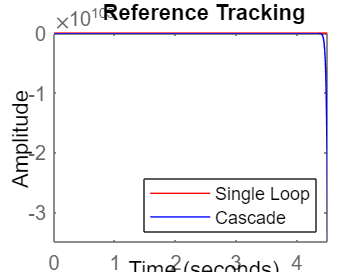


% single loop system for reference tracking 
sys1 = feedback(G*C,1);
sys1.Name = 'Single Loop';

% cascade system for reference tracking
sys2 = feedback(clsys*tfPendulum*C1,1); 
sys2.Name = 'Cascade';

% plot step response
figure;
step(sys1,'r',sys2,'b')
legend('show','location','southeast')
title('Reference Tracking')